**Chapter 9 Reading + Examples**

Section 9.1

This chapter presents three main methods of semi-parametric and non-parametrix density estimation and their variants: histograms, kernel density estimates, and finite mixtures.

MSE, MISE, and MIAE are covered in page 302 of the book. These methods to measure error are used in the estimated functions throughout Ch. 9.

Section 9.2 -- Histograms

Histograms are a graphical way of describing data. It conveys how a data set is distributed, reveals modes, bumps, and provides information about relative frequencies of observations.

The problem with this tool is that the total area represented by the bins does not add up to 1, making them not valid probability density estimates.

Histograms have a smoothing parameter, often referred to as h, which sets the bin width. Small values of h yields histograms with a lot variation, while larger values of h yields histograms that are a lot smoother.

Histograms are cool, and both univariate and multivariate histograms are covered in-depth in this chapter. I'm skipping these details to focus on what's primarily covered in class.

Section 9.3 -- Kernel Density Estimates

The steps to generate a univariate kernel are the following:

- Choose a kernel, a smoothing parameter h, and the domain over which to evaluate f^(x)

- For each X_i, evaluate the following kernel at all x in the domain: K_i = K((x-X_i)/h) s.t. i = 1, ... , n.

- Weight each curve by 1/h.

- For each x, take the averae of the weighted curves.

Example 9.6: This example shows how to obtain the kernel density estimate for a data set using the standard notmal density as the kernel.

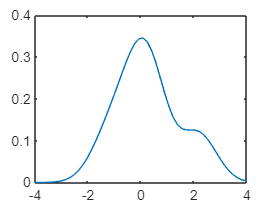

% generate data
n = 10;
data = randn(1,n);

% selecting domain
x = linspace(-4,4,50);
fhat = zeros(size(x));
h = 1.06*n^(-1/5);

%hold on
for i = 1:n
    f = exp(-(1/(2*h^2))*(x-data(i)).^2)/sqrt(2*pi)/h;
    %plot(x,f/(n*h));
    fhat = fhat+f/n;
end

plot(x,fhat);
hold off

Very pretty graph. It's important to note, parameter h determines the amount of smoothing we have in our kernel density plot. Smaller values of h will yield bumpy and rougher outputs, while larger values will yield smoother and more simplified curves.

See pg 330 Table 2 to see a summary of Univariate Probability Density Estimators and the Normal Reference Rule.

Section 9.4 -- Finite Mixtures

Finite mixtures are useful because we get to avoid having to choose a smoothing parameter h; however, in turn w have to determine the number of "terms" in the mixture.

This method assumes the density f(x) can be modeled as the sum of c weighted densities, with c << n.

Example 9.8

The following example shows how to evaluate a finite mixture model at a given x. We construct the curve for three term finite mixture model, where the component densities are taken to be normal.

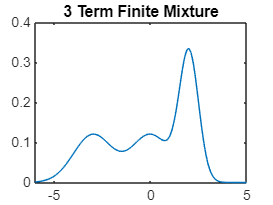

% Create a domain x for the mixture.
x = linspace(-6,5);

% Create a model - normal components used.
mix = [0.3 0.3 0.4];
mus = [-3 0 2];
vars = [1 1 0.5];
nterm = 3;

fhat = zeros(size(x));
for i = 1:nterm
    fhat = fhat + mix(i)*normpdf(x, mus(i), vars(i));
end

plot(x,fhat)
title('3 Term Finite Mixture')

Section 9.5 -- Generating Random Variables

In the